# calibra_ejez

Calculates the calibration matrix from the static positions of two triads of accelerometers and magnetic sensors. 

## Syntax

Mrot=calibra_ejez(AccXsens, MagXsens, num_posiciones, t_movimiento, vCALIBRA, k_inicial, f_s, t_espera_calibra);

## Description

`calibra_ejez(AccXsens, MagXsens, num_posiciones, t_movimiento, vCALIBRA, k_inicial, f_s, t_espera_calibra)` se dispone de señales de sendas triadas de acelerómetros y sensores magnéticos de un IMU, `AccXsens y MagXsens `como representa la figura:  

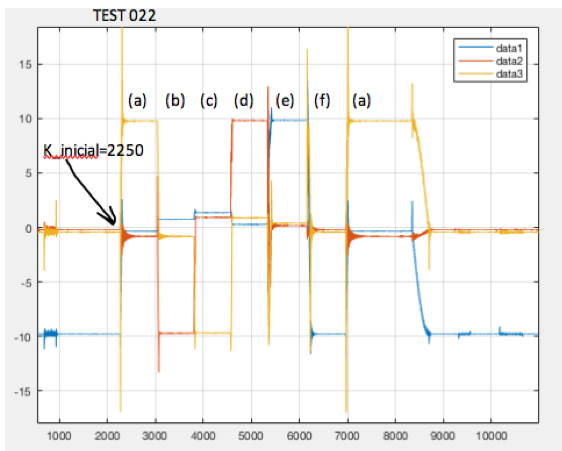

and that were generated by placing the sensor in orthogonal num_positions orientations, following the rotational calibration procedure. In the example of the figure there are 6 orientations, (a)-(f) and return to the initial (a). For each orientation we know the time it takes to reach it `t_movimiento`, and its description in the form of orientation matrix, in the rows of the matrix `vCALIBRA`, which in this case is 6x9. The initial instant `k_inicial` and the sampling frequency `f_s` are also known, the first usually known by visual inspection of the data.

## Examples

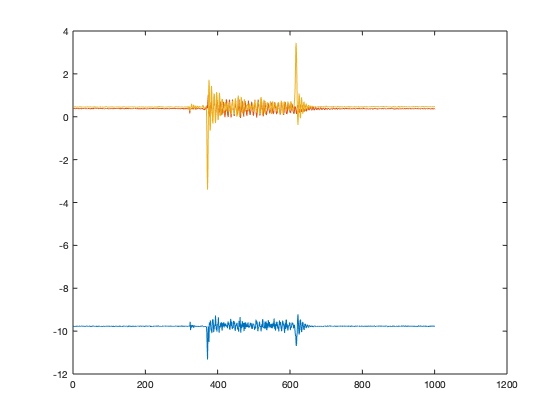

% Cargamos los datos de un experimento de calibracion ya conocido:
filename = '00500686-xsens.txt';
[Counter,Temperature,Acc_X,Acc_Y,Acc_Z,Gyr_X,Gyr_Y,Gyr_Z,Mag_X,Mag_Y,Mag_Z] = importfile_xsens(filename);
plot(AccXsens(1000:2000,:));

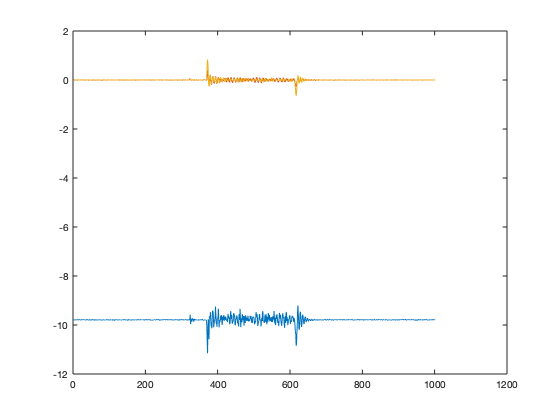


% Matriz de calibracion:
Mrot=calibra_ejez(AccXsens, MagXsens, num_posiciones, t_movimiento,...
    vCALIBRA, k_inicial, f_s, t_espera_calibra);
% Utilizacion: calibracion de los datos:
accs_cal=(Mrot*AccXsens(1:end,:)')';
plot(accs_cal(1000:2000,:));